# Detailed Inspection Pipeline

This live script complements the Defect Detection Report. The Detection Report's per-image demo in section 2.3 shows only the result of inspectPart.m on an image. This script is a more detailed view of what goes in inside the detection function, `inspectPart.m`. All images and tables produced here are all made from code, station by station, the function leaves a trail of its actions, inspecting an image and ultimately giving you a result.

NOTE: This file uses a small sample of the actual dataset. For reproducibility, you can replace the folder with the actual detector. 

This section initializes the whole pipeline, Click 'Run' or 'Run All' before you move the slider. To get rid of the "`Trained network not found locally" `simply press 'Run' again, since by the second run you will have the trained AI installed.

%% Initializing variables, .mat files, and creating file pathing
[repoDir, imagesDir, masksDir, net, netClassNames, imdsSample, numSample, trueLabelsAll] = initPipeline();

% To change the 20 img small demo to a full dataset, go to initPipeline() in the helper function section for more info

## Station 0: Choose an Image

%% ===================== INTERACTIVE IMAGE SELECTOR =========================
% Pick which sample image to inspect.
imageIndex = 12;

%% ===================== INSPECTION RESULT FOR SELECTED IMAGE ================
imageIndex = max(1, min(numSample, round(imageIndex)));   % clamp to valid range

I = readimage(imdsSample, imageIndex);
[~, thisName, thisExt] = fileparts(imdsSample.Files{imageIndex});
trueLabel = trueLabelsAll(imageIndex);

fprintf("\n=== Image %d of %d: %s%s (true label: %s) ===\n", ...
    imageIndex, numSample, thisName, thisExt, trueLabel);


=== Image 12 of 20: defect_0001.png (true label: FAIL) ===


## Station 1: Classical Detection Mask

### 1.1 The Masks

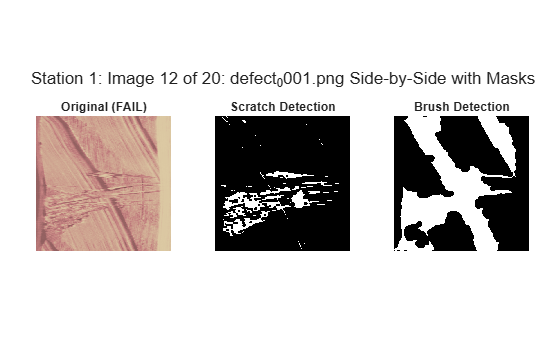

% ---- Classical Evidence Extraction -----------------------
[scratchMask, scratchProps] = scratchDetection(I); % Debug remove here since it prints twice if so 
[brushMask,   brushProps]   = brushDetection(I);

% Combined evidence overlay and metrics
evidenceOverlay = scratchMask | brushMask;
evidenceMetrics = mergeEvidence(scratchProps, brushProps, evidenceOverlay);

% Side-by-side visualization
figure;
tiledlayout(1, 3, "TileSpacing", "loose", "Padding", "compact");

nexttile;
imshow(I);
title(sprintf("Original (%s)", trueLabel));

nexttile;
imshow(scratchMask);
title("Scratch Detection");

nexttile;
imshow(brushMask);
title("Brush Detection");
sgtitle(sprintf("Station 1: Image %d of %d: %s%s Side-by-Side with Masks", imageIndex, numSample, thisName, thisExt));

### 1.2 Evidence Metrics

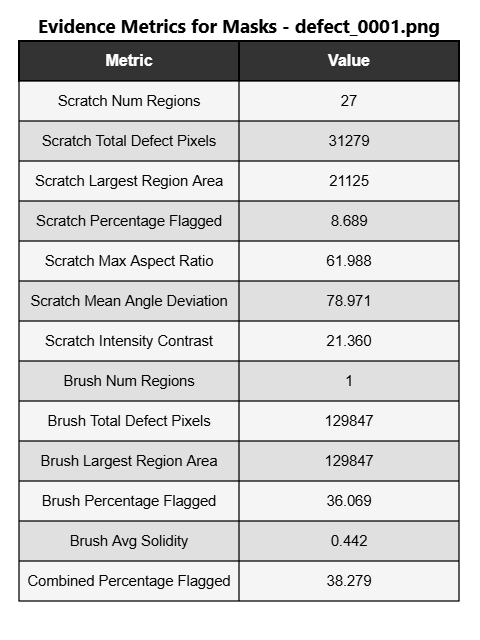


% ---- Evidence metrics table -------------------------------
headers = {"Metric", "Value"};

rows = {
    "Scratch Num Regions",          num2str(evidenceMetrics.scratch_NumRegions, '%d');
    "Scratch Total Defect Pixels",  num2str(evidenceMetrics.scratch_TotalDefectPixels, '%d');
    "Scratch Largest Region Area",  num2str(evidenceMetrics.scratch_LargestRegionArea, '%d');
    "Scratch Percentage Flagged",   num2str(evidenceMetrics.scratch_PercentageFlagged, '%.3f');
    "Scratch Max Aspect Ratio",     num2str(evidenceMetrics.scratch_MaxAspectRatio, '%.3f');
    "Scratch Mean Angle Deviation", num2str(evidenceMetrics.scratch_MeanAngleDeviation, '%.3f');
    "Scratch Intensity Contrast",   num2str(evidenceMetrics.scratch_IntensityContrast, '%.3f');

    "Brush Num Regions",            num2str(evidenceMetrics.brush_NumRegions, '%d');
    "Brush Total Defect Pixels",    num2str(evidenceMetrics.brush_TotalDefectPixels, '%d');
    "Brush Largest Region Area",    num2str(evidenceMetrics.brush_LargestRegionArea, '%d');
    "Brush Percentage Flagged",     num2str(evidenceMetrics.brush_PercentageFlagged, '%.3f');
    "Brush Avg Solidity",           num2str(evidenceMetrics.brush_AvgSolidity, '%.3f');
    "Combined Percentage Flagged",  num2str(evidenceMetrics.combined_PercentageFlagged, '%.3f');
};

drawMetricsTable(headers, rows, sprintf("Evidence Metrics for Masks - %s%s", thisName, thisExt));

## Station 2: AI Classifier 

Ai's output

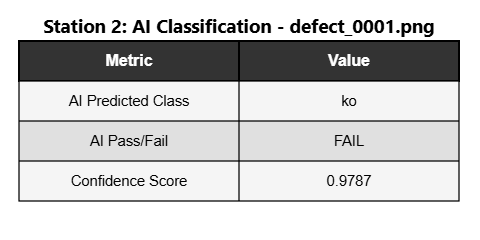

% ---- AI classification ---------------------------------
imgForNet = prepareForNet(I);
[aiLabelCat, scores] = classify(net, imgForNet);
aiLabelStr       = string(aiLabelCat);
confidenceScore  = max(scores);
aiRawLabel       = mapToPassFail(aiLabelStr, netClassNames);

% AI classification table 
headers = {"Metric", "Value"};

rows = {
    "AI Predicted Class",   char(aiLabelStr);
    "AI Pass/Fail",         char(aiRawLabel);
    "Confidence Score",     num2str(confidenceScore, '%.4f');
    };

drawMetricsTable(headers, rows, sprintf("Station 2: AI Classification - %s%s", thisName, thisExt) ...
    );

## Station 3: Baseline Decision

At this point, we have the classical mask and the AI's decision. In our function, we implemented a rule-based baseline that is capable of overriding the AI's decision. With the override, the all metrics for the final display are created.

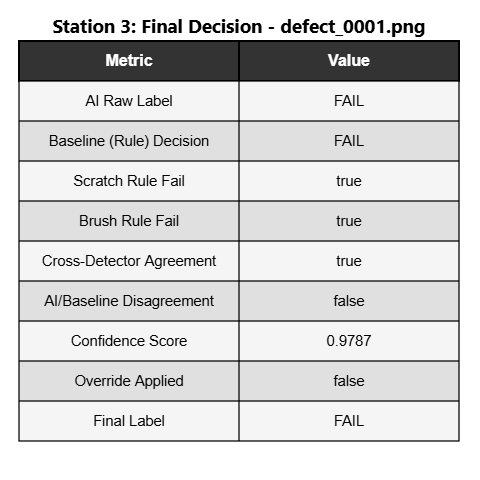

% ---- Rule-based classical evidence decisions -------------
[baselineDecision, scratchFail, brushFail] = decideRules(evidenceMetrics); 
% Check helper function for more details on the decision making

% ---- Flags: AI/classical evidence disagreement -------------
disagreementFlag       = ~strcmp(aiRawLabel, baselineDecision);
crossDetectorAgreement = scratchFail && brushFail;

% ---- Confidence-gated override ----------------------------
% If the AI isn't confident enough in its own call, defer to the
% classical rule-based baseline instead of trusting a low-confidence
% AI decision.
overrideApplied = confidenceScore < 0.75; % Threshold of confidence
if overrideApplied
    finalLabel = baselineDecision;
else
    finalLabel = aiRawLabel; % AI is the default unless its not confident
end

% ---- Final decision table ---------------------------------
headers = {"Metric", "Value"};

rows = {
    "AI Raw Label",             char(aiRawLabel);
    "Baseline (Rule) Decision", char(baselineDecision);
    "Scratch Rule Fail",        char(string(scratchFail));
    "Brush Rule Fail",          char(string(brushFail));
    "Cross-Detector Agreement", char(string(crossDetectorAgreement));
    "AI/Baseline Disagreement", char(string(disagreementFlag));
    "Confidence Score",         num2str(confidenceScore, '%.4f');
    "Override Applied",         char(string(overrideApplied));
    "Final Label",              char(finalLabel);
    };

drawMetricsTable(headers, rows, sprintf("Station 3: Final Decision - %s%s", thisName, thisExt));

## Station 4: Print the Results

Now the result is finally sent!

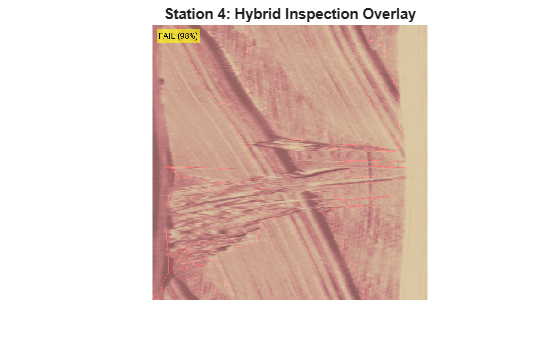


% ============================================================
% Package result
% ============================================================
result.finalLabel             = finalLabel;
result.aiRawLabel             = aiRawLabel; 
result.confidenceScore        = confidenceScore;
result.evidenceOverlay        = evidenceOverlay;
result.evidenceMetrics        = evidenceMetrics;
result.baselineDecision       = baselineDecision;
result.disagreementFlag       = disagreementFlag;
result.overrideApplied        = overrideApplied; % Added override after seeing classical outperforming ai classifier on simple defects
result.crossDetectorAgreement = crossDetectorAgreement;

figure('Name', 'Station 4: Hybrid Inspection Overlay');
imshow(labelOverlayImage(I, evidenceOverlay, finalLabel, confidenceScore, disagreementFlag));

title('Station 4: Hybrid Inspection Overlay');

## All Helper Functions

% (They were originally in the section that needed them, but that was too messy and ineffecient)
% ---- INSPECT PART HELER FUNCTION: Merge classical evidence structs into one ----
function evidence = mergeEvidence(scratchProps, brushProps, combinedMask)
evidence = struct();
sFields = fieldnames(scratchProps);
for i = 1:numel(sFields)
    evidence.(['scratch_' sFields{i}]) = scratchProps.(sFields{i});
end

bFields = fieldnames(brushProps);
for i = 1:numel(bFields)
    evidence.(['brush_' bFields{i}]) = brushProps.(bFields{i});
end

% Overall combined metric
evidence.combined_PercentageFlagged = 100 * nnz(combinedMask) / numel(combinedMask);
end

% ----SEGMENT DEFECT DEMO's draw talbe helper function ------%
function drawMetricsTable(headers, rows, figTitle)
% Draws a simple bordered table as a regular figure (docks inline in
% the Live Script, same as any other figure() call)
nCols = numel(headers);
nRows = size(rows, 1);

cellW = 220; cellH = 40; marginX = 20; marginY = 40;
figW = cellW * nCols + 2 * marginX;
figH = cellH * (nRows + 1) + 2 * marginY;

figure('Position', [80 80 figW figH]);
ax = axes('Units', 'pixels', 'Position', [marginX marginY cellW*nCols cellH*(nRows+1)]);
axis(ax, [0 nCols 0 nRows+1]);
set(ax, 'YDir', 'reverse');
axis(ax, 'off');
hold(ax, 'on');

headerColor = [0.20 0.20 0.20];
rowColors = {[0.96 0.96 0.96], [0.88 0.88 0.88]};   % light zebra striping

% Header row
for j = 1:nCols
    rectangle(ax, 'Position', [j-1, 0, 1, 1], 'FaceColor', headerColor, 'EdgeColor', 'k', 'LineWidth', 1.5);
    text(ax, j-0.5, 0.5, headers{j}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
        'FontWeight', 'bold', 'Color', 'w', 'FontSize', 12);
end
% Data rows
for i = 1:nRows
    rc = rowColors{mod(i-1, 2) + 1};
    for j = 1:nCols
        rectangle(ax, 'Position', [j-1, i, 1, 1], 'FaceColor', rc, 'EdgeColor', 'k', 'LineWidth', 1);
        text(ax, j-0.5, i+0.5, rows{i,j}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
            'Color', 'k', 'FontSize', 11);
    end
end

    if nargin > 2 && ~isempty(figTitle)
    t = title(ax, figTitle, 'Color', 'k', 'Interpreter', 'none', ...
        'FontWeight', 'bold', 'FontName', 'Segoe UI', 'FontSize', 14);
    t.Visible = 'on';
    end
end

%% ---- Helper Function from inspectPart.m----
function imgForNet = prepareForNet(image)
% Standardize size/channels to what the network expects (224x224x3).
imgForNet = imresize(image, [224 224]);
if size(imgForNet, 3) == 1
    imgForNet = repmat(imgForNet, [1 1 3]);
end
if ~isa(imgForNet, 'uint8')
    imgForNet = im2uint8(imgForNet);
end
end

% ---- Also from inspectPart, Map network's raw class name to PASS/FAIL ----
function label = mapToPassFail(aiLabelStr, classNames)
% classNames are set in the order used when training, e.g. {'ok';'ko'}.
% 'ok'  -> PASS
% 'ko'  -> FAIL
okNames = ["ok", "pass", "good"];
if any(strcmpi(aiLabelStr, okNames))
    label = "PASS";
else
    label = "FAIL";
end
end

% ---- HELPERS FROM INSPECT PART: Conservative rule-based baseline decision ----
function [decision, scratchFail, brushFail] = decideRules(evidence)
% Thresholds finalized from empirical batch analysis

% SCRATCH: LargestRegionArea is the valid
% discriminator. LargestRegionArea, measured on a hand-picked scratch-defect batch 
% vs. the clean-image batch showed a clean, zero-overlap
% gap: clean max ~123px, defect min ~871px. Threshold of 300 sits
% comfortably in that gap. Validated end-to-end: 100% recall (50/50)
% on the first 50 defects batch, 0 false positives contributed on the
% clean batch (first 50 clean images in train).

% LIMITATIONW: This threshold is tuned for moderate/obvious
% scratches, not super-thin scratches in 'ko' images 80 and onward. A super-thin scratch's surviving
% blob area (e.g. Defect 121: 120px) sits well below 300, inside the
% clean-image noise range. This threshold is intentionally NOT
% lowered to try to catch super-thin cases, since that would reopen the
% clean-image false-positive problem this fix solved.
scratchFail = evidence.scratch_LargestRegionArea > 300;

% BRUSH: requires both a nonzero detection AND a large-enough flagged
% area. The >2% cutoff sits in the gap between small grain-noise false
% positives (max ~1.46% in a 20 img batch) and real brush defects (min
% ~4.24% from the first 20). 

% LIMITATION: This mask not resolve the large false-positive
% mode caused by curved/wavy grain fooling the FFT notch filter on some
% clean images.

brushFail = evidence.brush_NumRegions > 0 && evidence.brush_PercentageFlagged > 2;

% Both detectors are strong on their own, so they will detect what they
% are supposed to detect
if scratchFail || brushFail
    decision = "FAIL";
else
    decision = "PASS";
end
end


%% ----build a visual overlay for debug display ----
function outImg = labelOverlayImage(image, mask, label, score, disagreement)
outImg = im2uint8(image);
if size(outImg, 3) == 1
    outImg = repmat(outImg, [1 1 3]);
end

% Tint suspicious regions red
boundaries = bwperim(mask);
redChannel = outImg(:,:,1);
redChannel(boundaries) = 255;
outImg(:,:,1) = redChannel;

txt = sprintf('%s (%.0f%%)', label, score * 100);
if disagreement
    txt = [txt ' -- DISAGREEMENT'];
end
outImg = insertText(outImg, [10 10], txt, 'FontSize', 18, ...
    'BoxColor', 'yellow', 'TextColor', 'black');
end

function [repoDir, imagesDir, masksDir, net, netClassNames, imdsSample, numSample, trueLabelsAll] = initPipeline()
    % Creating file path and initializing stuff. 
    try
        scriptDir = fileparts(matlab.desktop.editor.getActiveFilename());
    catch
        scriptDir = fileparts(mfilename("fullpath"));
    end
    
    repoDir = fileparts(scriptDir);   % scripts/ -> repo root
    
    % initialize image variables
    sampleDir = fullfile(repoDir, 'imageSampleSets', sprintf('sample_test_02'));
    imagesDir = fullfile(sampleDir, 'images');
    masksDir  = fullfile(sampleDir, 'masks');
    
    % Full dataset override (uncomment and edit):
    % imagesDir = "C:/.../BTAD/02/test/ko";
    % masksDir  = "C:/.../BTAD/02/ground_truth/ko";
    % sampleDir = imagesDir;  % kept only so any later code referencing sampleDir doesn't break
    
    % You may also need to adjust the slider in Station 0 to fit with how many
    % are in the dataset chosen. OR completely remove it and just use the number index
    
    % images/ is always required; masks/ is only required for the ko (defect) set,
    % since ok (clean) images have no ground_truth annotations.
    [~, imagesParentFolder] = fileparts(imagesDir);
    isDefectSet = strcmpi(imagesParentFolder, "ko") || contains(imagesDir, "defect", "IgnoreCase", true);
    
    if isDefectSet
        msg = sprintf(['Could not find:\n  %s\n  %s\n', ...
            'Make sure imagesDir/masksDir point at valid folders, and that ', ...
            'masksDir points at the matching ground_truth/ subfolder ', ...
            '(not a masks/ sibling) if using a full dataset.'], imagesDir, masksDir);
        assert(exist(imagesDir, 'dir') == 7 && exist(masksDir, 'dir') == 7, msg);
    else
        msg = sprintf(['Could not find:\n  %s\n', ...
            'Make sure imagesDir points at a valid folder.'], imagesDir);
        assert(exist(imagesDir, 'dir') == 7, msg);
    end
    
    
    % initialize net variables
    netFileName    = "1785125303951_trainedInspectAI.mat";
    netMatFile     = fullfile(repoDir, netFileName);
    netReleaseURL  = "https://github.com/AndyV0/Defect-Detection-Pipeline---Wood-Grain/releases/download/1.0/1785125303951_trainedInspectAI.mat";
    
    if ~isfolder(sampleDir)
        warning("batchTestRunner:noSampleImages", ...
            "%s not found. Image data not found.", sampleDir);
        return;
    end
    
    % Download the trained net from GitHub Releases if it isn't already here
    if ~isfile(netMatFile)
        fprintf("Trained network not found locally. Downloading from GitHub Releases...\n");
        fprintf("  %s\n", netReleaseURL);
        try
            websave(netMatFile, netReleaseURL);
            fprintf("Download complete: %s\n", netMatFile);
        catch ME
            if isfile(netMatFile)
                delete(netMatFile);
            end
            error("batchTestRunner:downloadFailed", ...
                "Could not download the trained network from:\n  %s\nError: %s\n" + ...
                "Check that netReleaseURL above is correct, or manually download " + ...
                "%s from the repo's Releases page and place it in %s.", ...
                netReleaseURL, ME.message, netFileName, repoDir);
        end
    end
    
    % Load the net and its class names 
    S = load(netMatFile);
    net           = S.netTransfer;
    netClassNames = S.classNames;
    
    addpath(genpath(repoDir)); % Create path for everything else
    
    msg = sprintf(['Could not find imageSampleSets/sample_test_02/images and /masks.\n', ...
        'Make sure the repo was cloned (not just this one file downloaded), ', ...
        'and that imageSampleSets/sample_test_02/ contains the demo images/masks.']);
    assert(exist(imagesDir, 'dir') == 7 && exist(masksDir, 'dir') == 7, msg);
    
    imdsSample = imageDatastore(imagesDir);   % flat images/ folder, no subfolders
    numSample = numel(imdsSample.Files);
    
    % True labels come from filename PREFIX ("clean_" / "defect_"), not
    trueLabelsAll = strings(numSample, 1);
    for i = 1:numSample
        filePath = imdsSample.Files{i};
        [folderPath, name, ~] = fileparts(filePath);
        [~, parentFolder] = fileparts(folderPath);
        
        if strcmpi(parentFolder, "ok")
            trueLabelsAll(i) = "PASS";
        elseif strcmpi(parentFolder, "ko")
            trueLabelsAll(i) = "FAIL";
        elseif startsWith(name, "clean_", "IgnoreCase", true)
            trueLabelsAll(i) = "PASS";
        elseif startsWith(name, "defect_", "IgnoreCase", true)
            trueLabelsAll(i) = "FAIL";
        else
            warning("batchTestRunner:unrecognizedFilePrefix", ...
                "File '%s' doesn't start with 'clean_' or 'defect_' -- true label unknown, marking as FAIL by default. Check this filename.", name);
            trueLabelsAll(i) = "FAIL";
        end
    end
%%
end